## Program to simulate and estimate MGARCH models.

© MTGP 2026

clear
% Eurostoxx50
file=xlsread("AdvStats_Groups.xlsx","FX Mkt");

date=datetime(file(:,1), 'ConvertFrom','excel');
price1=file(:,2);
price2=file(:,7);
price3=file


%PEUR = [datenum(Eurostoxx50(:,3),Eurostoxx50(:,2),Eurostoxx50(:,1)) Eurostoxx50(:,4)];
%id = find(weekday(PEUR(:,1))==7|weekday(PEUR(:,1))==8); PEUR(id,:)=[];
% Ibex-35
%load Ibex.txt
%PIBX = [datenum(Ibex(:,3),Ibex(:,2),Ibex(:,1)) Ibex(:,4)];
%id = find(weekday(PIBX(:,1))==7|weekday(PIBX(:,1))==8); PIBX(id,:)=[];
% DAX
%load dax.txt
%PDAX = [datenum(dax(:,3),dax(:,2),dax(:,1)) dax(:,4)]; 
%id = find(weekday(PDAX(:,1))==7|weekday(PDAX(:,1))==8); PDAX(id,:)=[];

## **UNIVARIATE GARCH(1,1)**

1) GARCH(1,1)

%Y = [date price]
% Estimate individual GARCH(1,1) models
% EMU
Mdl = garch(1,1); 
y1 = 100.*diff(log(price(:,1))); 
EstMdl = estimate(Mdl,y1); 

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue 
                _________    _____________    __________    ________

    Constant    0.0012181     0.00020157        6.0433      1.51e-09
    GARCH{1}      0.95968      0.0030348        316.22             0
    ARCH{1}      0.036882      0.0029933        12.321             0



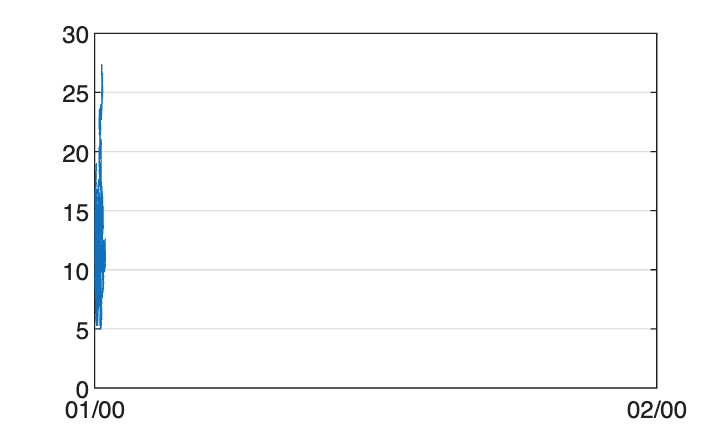

[ht] = infer(EstMdl,y1); % conditional volatility
figure;
plot(price(2:end,1),sqrt(365*ht)); %annualize. We should use 252.
datetick('x','mm/yy');
grid on;

%Corrección
file = xlsread("AdvStats_Groups.xlsx","FX Mkt");

date  = datetime(file(:,1), 'ConvertFrom','excel');
price1 = file(:,2);
price2 = file(:,7);
price3 = file(:,);

Mdl = garch(1,1); 
y1 = 100.*diff(log(price)); 
EstMdl = estimate(Mdl,y1); 

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue 
                _________    _____________    __________    ________

    Constant    0.0012181     0.00020157        6.0433      1.51e-09
    GARCH{1}      0.95968      0.0030348        316.22             0
    ARCH{1}      0.036882      0.0029933        12.321             0



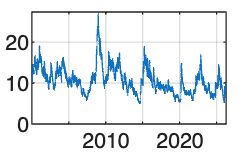

ht = infer(EstMdl,y1);

figure
plot(date(2:end), sqrt(365*ht))
grid on


$$h_{t\;} =\underset{\left(12\ldotp 87\right)}{0\ldotp 018} +\underset{\left(287\ldotp 89\right)}{0\ldotp 92} h_{t-1} +\underset{\left(25\ldotp 70\right)}{0\ldotp 07} \varepsilon_{t-1}$$


% ES
Mdl = garch(1,1); 
y2 = 100.*diff(log(PIBX(:,2))); EstMdl = estimate(Mdl,y2);

Unrecognized function or variable 'PIBX'.

[ht] = infer(EstMdl,y2);  % conditional volatility
figure;
plot(PIBX(2:end,1),sqrt(365*ht)); 
datetick('x','mm/yy');
grid on;


$$h_{t\;} =\underset{\left(11\ldotp 27\right)}{0\ldotp 020} +\underset{\left(270\ldotp 79\right)}{0\ldotp 91} h_{t-1} +\underset{\left(28\ldotp 07\right)}{0\ldotp 08} \varepsilon_{t-1}$$


% DE
Mdl = garch(1,1); y3 = 100.*diff(log(PDAX(:,2))); EstMdl = estimate(Mdl,y3);
[ht] = infer(EstMdl,y3);  % conditional volatility
figure;
plot(PDAX(2:end,1),sqrt(365*ht)); 
datetick('x','mm/yy');
grid on;


$$h_{t\;} =\underset{\left(11\ldotp 57\right)}{0\ldotp 018} +\underset{\left(267\ldotp 94\right)}{0\ldotp 92} h_{t-1} +\underset{\left(22\ldotp 85\right)}{0\ldotp 07} \varepsilon_{t-1}$$


% ----------
% QUESTIONS:
% ----------
% GARCH{1} + ARCH{1} = 1.00 (IGARCH?)
% Unconditional volatility (sigma): 
% omega/(1-alpha - beta) = 1.1965e-06/(1-0.93858- 0.05326 ) = 0.00014663 = 0.0002
% var(y) = 0.0001518 = 0.0002 ¿approx sigma?


2) EGARCH(1,1)

% Estimate individual GARCH(1,1) models
% EMU
% Analizar qué terminos dependen de epsilon y como afectan a los dos
% primeros terminos
Mdl = egarch(1,1); 
y1 = 100.*diff(log(price(:,2))); 
EstMdl = estimate(Mdl,y1);
[ht] = infer(EstMdl,y1);  % conditional volatility
figure;
plot(price(2:end,1),sqrt(365*ht)); 
datetick('x','mm/yy');
grid on;


$$\ln \;h_{t\;} =\underset{\left(18\ldotp 21\right)}{0\ldotp 015} +\underset{\left(1127\ldotp 00\right)}{0\ldotp 98} \ln \;h_{t-1} +\underset{\left(26\ldotp 41\right)}{0\ldotp 11} \left\lbrack \frac{|\varepsilon_{t-1} |}{\sigma_{t-1} }-\sqrt{\frac{2}{\pi \;}}\right\rbrack -\underset{\left(-34\ldotp 66\right)}{0\ldotp 10} \left(\frac{\varepsilon_{t-1} }{\sigma_{t-1} }\right)$$


% ES
Mdl = egarch(1,1); y2 = 100.*diff(log(PIBX(:,2))); EstMdl = estimate(Mdl,y2);
[ht] = infer(EstMdl,y2);  % conditional volatility
figure;
plot(PIBX(2:end,1),sqrt(365*ht)); 
datetick('x','mm/yy');
grid on;


$$\ln \;h_{t\;} =\underset{\left(20\ldotp 12\right)}{0\ldotp 017} +\underset{\left(957\ldotp 44\right)}{0\ldotp 98} \ln \;h_{t-1} +\underset{\left(25\ldotp 43\right)}{0\ldotp 12} \left\lbrack \frac{|\varepsilon_{t-1} |}{\sigma_{t-1} }-\sqrt{\frac{2}{\pi \;}}\right\rbrack -\underset{\left(-28\ldotp 64\right)}{0\ldotp 09} \left(\frac{\varepsilon_{t-1} }{\sigma_{t-1} }\right)$$


% DE
Mdl = egarch(1,1); y3 = 100.*diff(log(PDAX(:,2))); EstMdl = estimate(Mdl,y3);
[ht] = infer(EstMdl,y3);  % conditional volatility
figure;
plot(PDAX(2:end,1),sqrt(365*ht)); 
datetick('x','mm/yy');
grid on;


$$\ln \;h_{t\;} =\underset{\left(17\ldotp 78\right)}{0\ldotp 016} +\underset{\left(975\ldotp 30\right)}{0\ldotp 98} \ln \;h_{t-1} +\underset{\left(22\ldotp 13\right)}{0\ldotp 10} \left\lbrack \frac{|\varepsilon_{t-1} |}{\sigma_{t-1} }-\sqrt{\frac{2}{\pi \;}}\right\rbrack -\underset{\left(-34\ldotp 68\right)}{0\ldotp 10} \left(\frac{\varepsilon_{t-1} }{\sigma_{t-1} }\right)$$


## **MULTIVARIATE GARCH(1,1)**

Include the root for the MFE_Toolbox path. This page includes most used multivariate GARCH models: EWMA, CCC, DCC.

addpath(genpath('C:\TRABAJO\Project 6 = Banking Sector\matlab\mfe-toolbox-main\'));
%Genpath is for adding the subfolders. 

Selecting common dates for all the series

[C,IA,IB] = intersect(price(:,1),PIBX(:,1));
y0 =[C PEUR(IA,2) PIBX(IB,2)]; % it's for common dates 
[C,IA,IB] = intersect(y0(:,1),PDAX(:,1));
y = [C y0(IA,2:end) PDAX(IB,2)];

Calculate daily log-returns 

lny = diff(log(y(:,2:end)));

Estimating EWMA (Risk-metrics)

lambda = 0.94;
Ht = riskmetrics(lny,lambda,cov(lny));

Storaging the conditional variance and correlation series.

for j=1:size(Ht,3);
    % conditional variance
    h1t(j,1) = Ht(1,1,j);
    h2t(j,1) = Ht(2,2,j);
    h3t(j,1) = Ht(3,3,j);
    % conditional covariance
    h12(j,1) = Ht(2,1,j);
    h13(j,1) = Ht(3,1,j);
    h23(j,1) = Ht(3,2,j);
    % conditional correlation
    ro12(j,1) = h12(j,1)./sqrt(h1t(j,1)*h2t(j,1));
    ro13(j,1) = h13(j,1)./sqrt(h1t(j,1)*h3t(j,1));
    ro23(j,1) = h23(j,1)./sqrt(h2t(j,1)*h3t(j,1));    
end

% Acumulo los resultados

H.h1.EWMA = [DatesF(2:end) 100.*sqrt(h1t.*252)];
H.h2.EWMA = [DatesF(2:end) 100.*sqrt(h2t.*252)];
H.h3.EWMA = [DatesF(2:end) 100.*sqrt(h3t.*252)];
H.h12.EWMA = [DatesF(2:end) ro12];
H.h13.EWMA = [DatesF(2:end) ro13];
H.h23.EWMA = [DatesF(2:end) ro23];

Figure: plotting the results

figure('units','normalized','outerposition',[0 0 1 1])
subplot(2,3,1);
plot(DatesF(2:end,1),100.*sqrt(h1t.*252));xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits');  grid on; title('$\hat{h}_t$ for Eurostoxx','Interpreter','latex');
set(gca,'FontSize',19);
subplot(2,3,2);
plot(DatesF(2:end,1),100.*sqrt(h2t.*252));xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{h}_t$ for Ibex-35','Interpreter','latex');
set(gca,'FontSize',19);
subplot(2,3,3);
plot(DatesF(2:end,1),100.*sqrt(h3t.*252));xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{h}_t$ for DAX','Interpreter','latex');
set(gca,'FontSize',19);
subplot(2,3,4);
plot(DatesF(2:end,1),ro12);xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{\rho}_t$ for Eurostoxx-Ibex35','Interpreter','latex');
set(gca,'FontSize',19);yline(nanmean(ro12));ylim([-1 1]);
subplot(2,3,5);
plot(DatesF(2:end,1),ro13);xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{\rho}_t$ for Eurostoxx-DAX','Interpreter','latex');
set(gca,'FontSize',19);yline(nanmean(ro13));ylim([-1 1]);
subplot(2,3,6);
plot(DatesF(2:end,1),ro23); xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{\rho}_t$ for Ibex35-DAX','Interpreter','latex');
set(gca,'FontSize',19); yline(nanmean(ro23)); ylim([-1 1]);

## CCC MULTIVARIATE GARCH(1,1)

% 
[parameters, ll, Ht, VCV, scores] = ccc_mvgarch(lny,[],1,0,1);
for j=1:size(Ht,3);
    % conditional variance
    h1t(j,1) = Ht(1,1,j);
    h2t(j,1) = Ht(2,2,j);
    h3t(j,1) = Ht(3,3,j);
    % conditional covariance
    h12(j,1) = Ht(2,1,j);
    h13(j,1) = Ht(3,1,j);
    h23(j,1) = Ht(3,2,j);
    % conditional correlation
    ro12(j,1) = h12(j,1)./sqrt(h1t(j,1)*h2t(j,1));
    ro13(j,1) = h13(j,1)./sqrt(h1t(j,1)*h3t(j,1));
    ro23(j,1) = h23(j,1)./sqrt(h2t(j,1)*h3t(j,1));    
end

% Acumulo los resultados

H.h1.CCC = [DatesF(2:end) 100.*sqrt(h1t.*252)];
H.h2.CCC = [DatesF(2:end) 100.*sqrt(h2t.*252)];
H.h3.CCC = [DatesF(2:end) 100.*sqrt(h3t.*252)];
H.h12.CCC = [DatesF(2:end) ro12];
H.h13.CCC = [DatesF(2:end) ro13];
H.h23.CCC = [DatesF(2:end) ro23];

figure('units','normalized','outerposition',[0 0 1 1])
subplot(2,3,1);
plot(DatesF(2:end,1),100.*sqrt(h1t.*252));xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits');  grid on; title('$\hat{h}_t$ for Eurostoxx','Interpreter','latex');
set(gca,'FontSize',19);
subplot(2,3,2);
plot(DatesF(2:end,1),100.*sqrt(h2t.*252));xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{h}_t$ for Ibex-35','Interpreter','latex');
set(gca,'FontSize',19);
subplot(2,3,3);
plot(DatesF(2:end,1),100.*sqrt(h3t.*252));xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{h}_t$ for DAX','Interpreter','latex');
set(gca,'FontSize',19);
subplot(2,3,4);
plot(DatesF(2:end,1),ro12);xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{\rho}_t$ for Eurostoxx-Ibex35','Interpreter','latex');
set(gca,'FontSize',19);yline(nanmean(ro12));ylim([0.5 1]);
subplot(2,3,5);
plot(DatesF(2:end,1),ro13);xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{\rho}_t$ for Eurostoxx-DAX','Interpreter','latex');
set(gca,'FontSize',19);yline(nanmean(ro13));ylim([0.5 1]);
subplot(2,3,6);
plot(DatesF(2:end,1),ro23); xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{\rho}_t$ for Ibex35-DAX','Interpreter','latex');
set(gca,'FontSize',19); yline(nanmean(ro23)); ylim([0.5 1]);

## Compare CCC and EWMA MGARCH

figure('units','normalized','outerposition',[0 0 1 1])
subplot(2,3,1);
plot(H.h1.EWMA(:,1),H.h1.EWMA(:,2)); hold on;
plot(H.h1.CCC(:,1),H.h1.CCC(:,2),'.'); 
datetick('x','yy'); grid on; legend('EWMA','CCC');
title('Eurostoxx50');xlim([H.h1.EWMA(1,1) H.h1.EWMA(end,1)]);
ylim([0 100]);set(gca,'FontSize',19);
subplot(2,3,4);
plot(H.h1.EWMA(:,1),log(H.h1.EWMA(:,2)./H.h1.CCC(:,2))); 
datetick('x','yy'); grid on;  title('ln(EWMA/CCC)');ylim([-0.6 0.4]);
xlim([H.h1.EWMA(1,1) H.h1.EWMA(end,1)]);
yline(0);set(gca,'FontSize',19);
subplot(2,3,2);
plot(H.h2.EWMA(:,1),H.h2.EWMA(:,2)); hold on;
plot(H.h2.CCC(:,1),H.h2.CCC(:,2),'.'); 
datetick('x','yy'); grid on; legend('EWMA','CCC');
title('Ibex35');xlim([H.h2.EWMA(1,1) H.h2.EWMA(end,1)]);
ylim([0 100]);set(gca,'FontSize',19);
subplot(2,3,5);
plot(H.h2.EWMA(:,1),log(H.h2.EWMA(:,2)./H.h2.CCC(:,2))); 
datetick('x','yy'); grid on; title('ln(EWMA/CCC)');
xlim([H.h2.EWMA(1,1) H.h2.EWMA(end,1)]);ylim([-0.6 0.4]);
yline(0);set(gca,'FontSize',19);
subplot(2,3,3);
plot(H.h3.EWMA(:,1),H.h3.EWMA(:,2)); hold on;
plot(H.h3.CCC(:,1),H.h3.CCC(:,2),'.'); 
datetick('x','yy'); grid on; legend('EWMA','CCC');
title('Dax');xlim([H.h3.EWMA(1,1) H.h3.EWMA(end,1)]);
ylim([0 100]);set(gca,'FontSize',19);
subplot(2,3,6);
plot(H.h3.EWMA(:,1),log(H.h3.EWMA(:,2)./H.h3.CCC(:,2))); 
datetick('x','yy'); grid on; title('ln(EWMA/CCC)');
xlim([H.h3.EWMA(1,1) H.h3.EWMA(end,1)]);ylim([-0.6 0.4]);
yline(0);set(gca,'FontSize',19);

## DCC MGARCH

[parameters, ll ,Ht, VCV, scores, diagnostics]=dcc(lny,[],1,0,1);
for j=1:size(Ht,3);
    % conditional variance
    h1t(j,1) = Ht(1,1,j);
    h2t(j,1) = Ht(2,2,j);
    h3t(j,1) = Ht(3,3,j);
    % conditional covariance
    h12(j,1) = Ht(2,1,j);
    h13(j,1) = Ht(3,1,j);
    h23(j,1) = Ht(3,2,j);
    % conditional correlation
    ro12(j,1) = h12(j,1)./sqrt(h1t(j,1)*h2t(j,1));
    ro13(j,1) = h13(j,1)./sqrt(h1t(j,1)*h3t(j,1));
    ro23(j,1) = h23(j,1)./sqrt(h2t(j,1)*h3t(j,1));    
end

% Acumulo los resultados

H.h1.DCC = [DatesF(2:end) 100.*sqrt(h1t.*252)];
H.h2.DCC = [DatesF(2:end) 100.*sqrt(h2t.*252)];
H.h3.DCC = [DatesF(2:end) 100.*sqrt(h3t.*252)];
H.h12.DCC = [DatesF(2:end) ro12];
H.h13.DCC = [DatesF(2:end) ro13];
H.h23.DCC = [DatesF(2:end) ro23];

figure('units','normalized','outerposition',[0 0 1 1])
subplot(2,3,1);
plot(DatesF(2:end,1),100.*sqrt(h1t.*252));xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits');  grid on; title('$\hat{h}_t$ for Eurostoxx','Interpreter','latex');
set(gca,'FontSize',19);ylim([0 100]);
subplot(2,3,2);
plot(DatesF(2:end,1),100.*sqrt(h2t.*252));xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{h}_t$ for Ibex-35','Interpreter','latex');
set(gca,'FontSize',19);ylim([0 100]);
subplot(2,3,3);
plot(DatesF(2:end,1),100.*sqrt(h3t.*252));xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{h}_t$ for DAX','Interpreter','latex');
set(gca,'FontSize',19);ylim([0 100]);
subplot(2,3,4);
plot(DatesF(2:end,1),ro12);xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{\rho}_t$ for Eurostoxx-Ibex35','Interpreter','latex');
set(gca,'FontSize',19);yline(nanmean(ro12));ylim([-1 1]);
subplot(2,3,5);
plot(DatesF(2:end,1),ro13);xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{\rho}_t$ for Eurostoxx-DAX','Interpreter','latex');
set(gca,'FontSize',19);yline(nanmean(ro13));ylim([-1 1]);
subplot(2,3,6);
plot(DatesF(2:end,1),ro23); xlim([y(1) y(end,1)]);
datetick('x','yy','Keeplimits'); grid on; title('$\hat{\rho}_t$ for Ibex35-DAX','Interpreter','latex');
set(gca,'FontSize',19); yline(nanmean(ro23)); ylim([-1 1]);